clear,clc

jl = 256.33e-06;
n = 1/80;

jm = 125e-04;
Bm = 6.78e-04;
Bl = 0.001;
Km = 0.957;
Ke = 0.957;
R = 1.45;
L = 5.4e-03;



jtd = jm+n^2*jl

jtd = 0.0125

Btd = Bm+n^2*Bl

Btd = 6.7816e-04

tau_t = L/R;
tau_c = jtd/Btd;

Ktd = Km/(Km*Ke+R*Btd)

Ktd = 1.0438

T1 = (tau_t*tau_c*R*Btd)/(Km*Ke+R*Btd)

T1 = 7.3623e-05

T2 = ((tau_t+tau_c)*R*Btd)/(Km*Ke+R*Btd)

T2 = 0.0198

s = tf('s');
G3 = (Ktd)/(T1*s^3+T2*s^2+s)

G3 =
 
               1.044
  -------------------------------
  7.362e-05 s^3 + 0.01977 s^2 + s
 
Continuous-time transfer function.



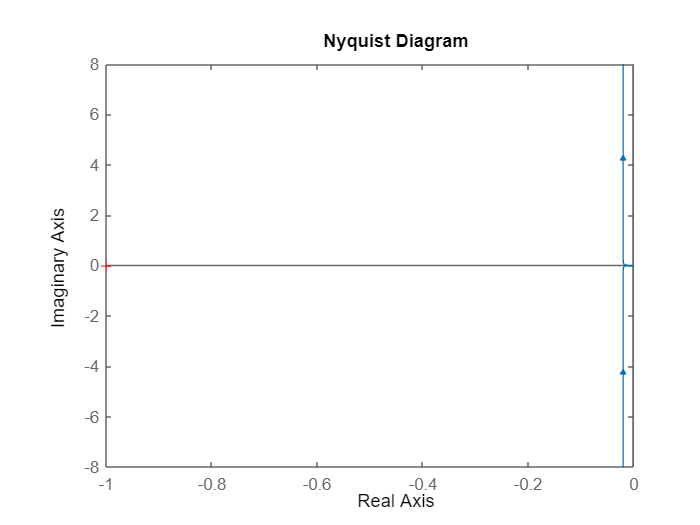

nyquist(G3)

H = feedback(G3,1)

H =
 
                   1.044
  ---------------------------------------
  7.362e-05 s^3 + 0.01977 s^2 + s + 1.044
 
Continuous-time transfer function.



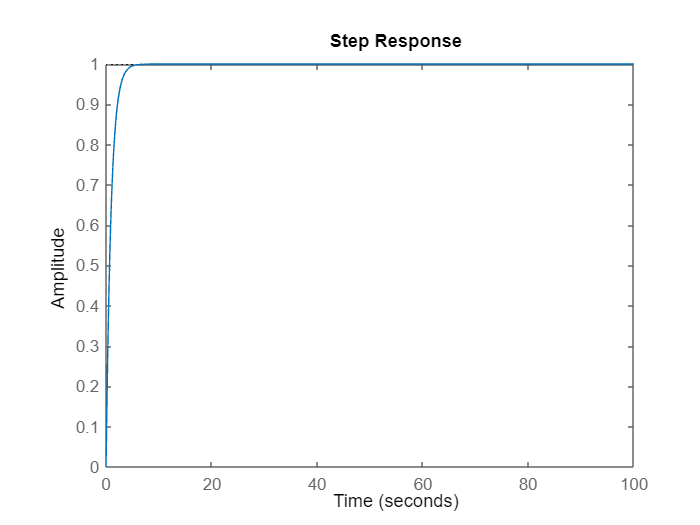

step(H,100)